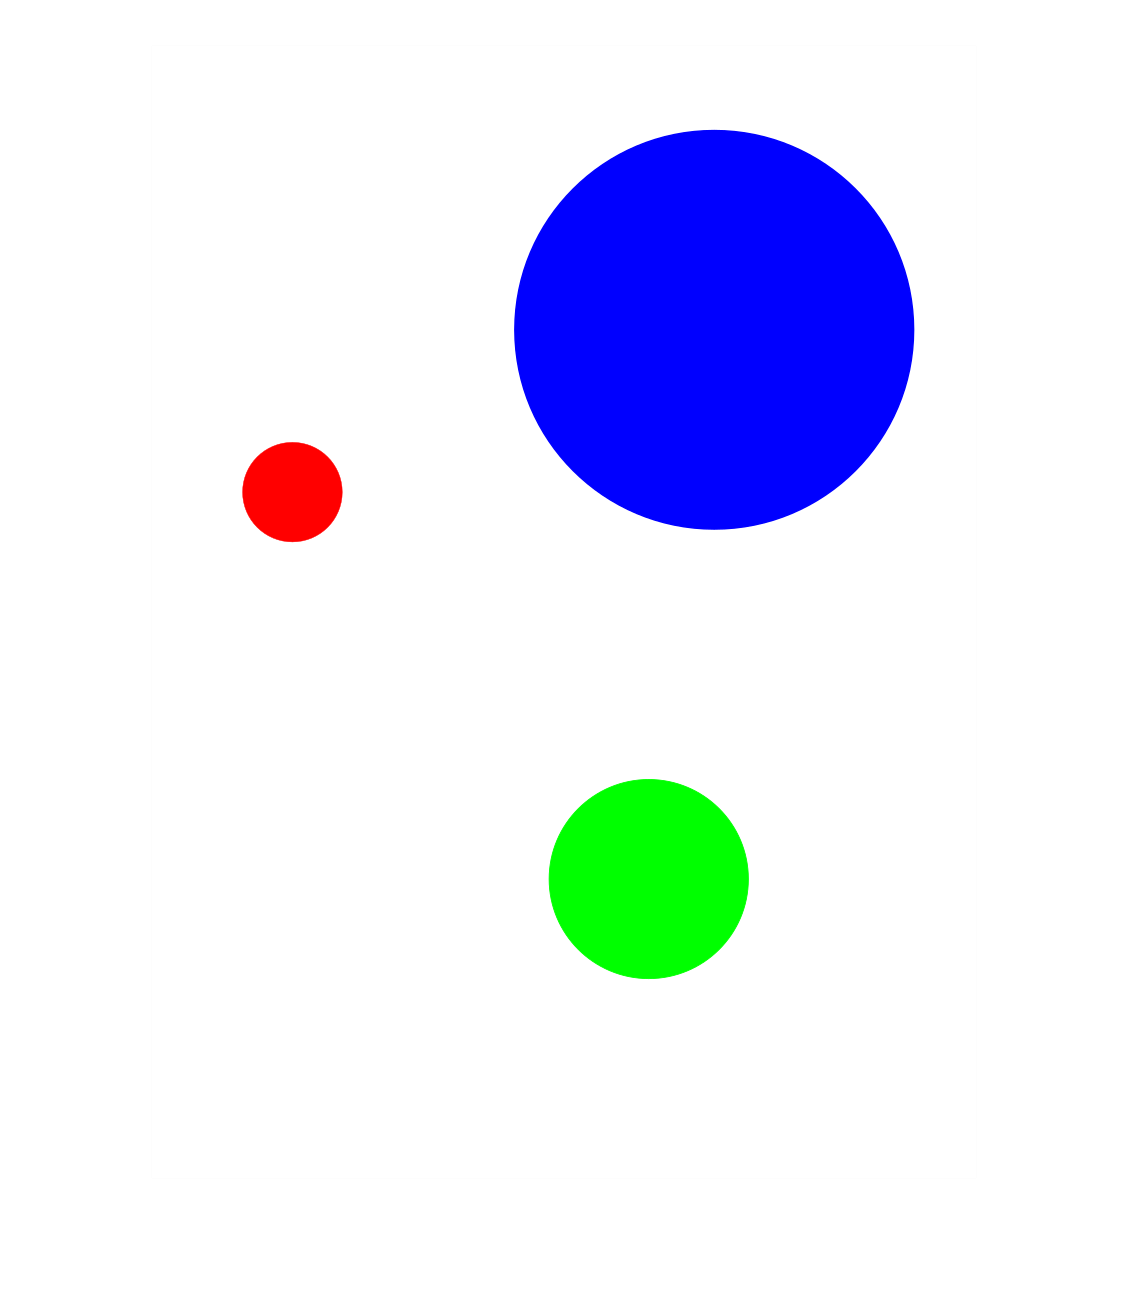

clear
clc

img = imread("radiusDots.png");
imshow(img)

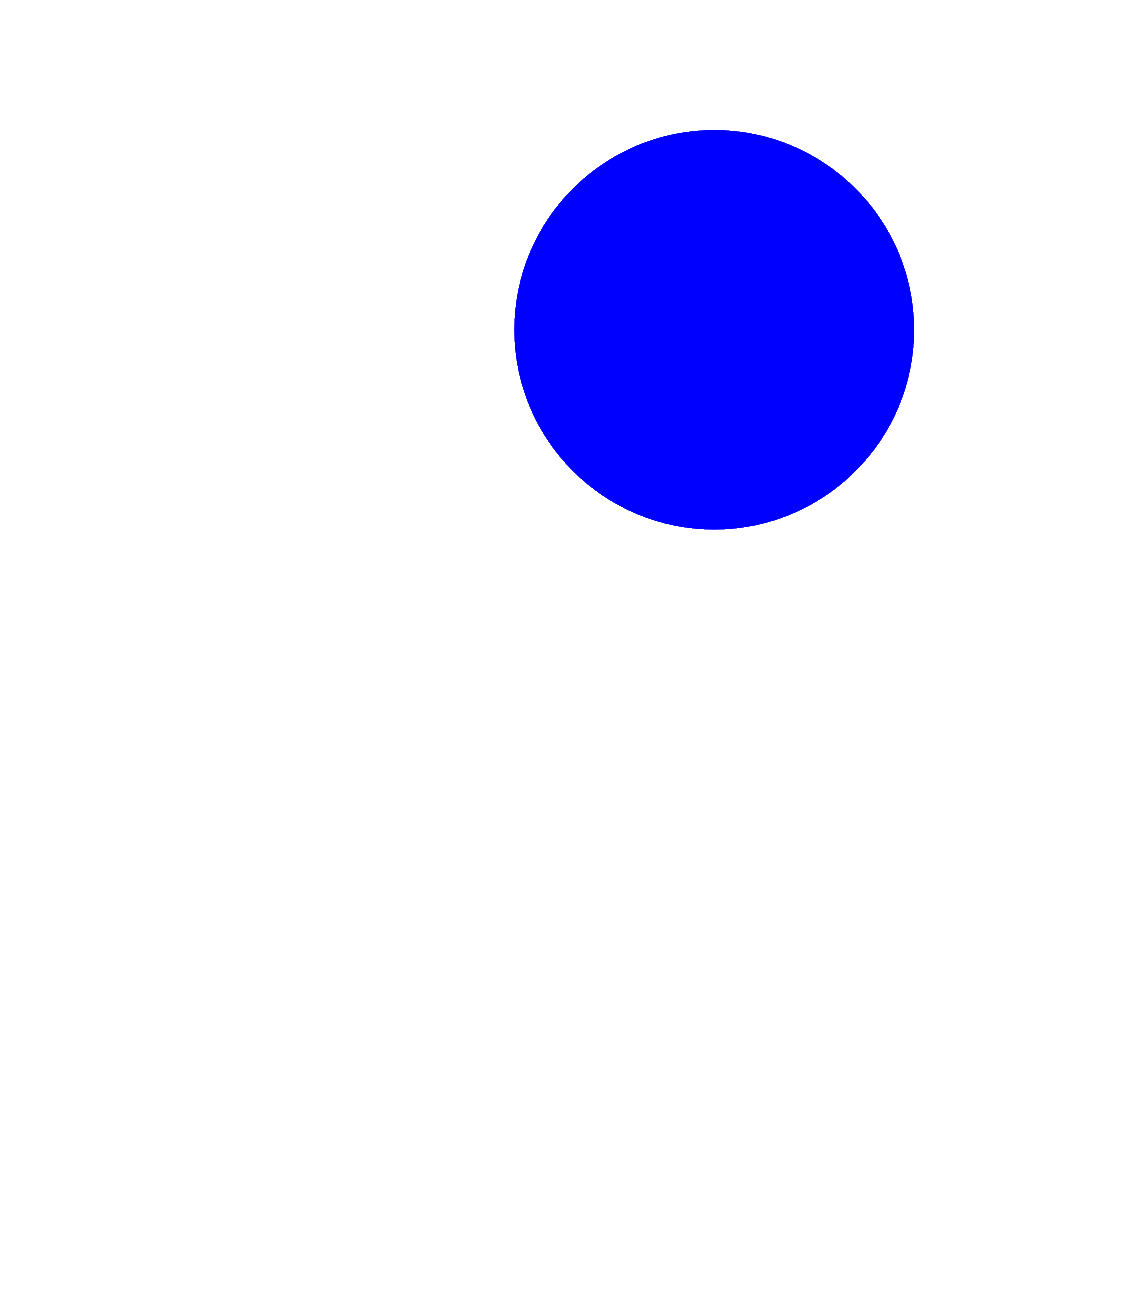


%Calculate the diameter, center and area of Blue Circle

%Extract Blue Circle
blueCircle = img;
m = blueCircle(:,:,1)<128 & blueCircle(:,:,2)<128 & blueCircle(:,:,3)>128;
m3(:,:,1) = m;
m3(:,:,2) = m;
m3(:,:,3) = m;
blueCircle(~m3) = 255;
%Show Blue Circle
imshow(blueCircle)

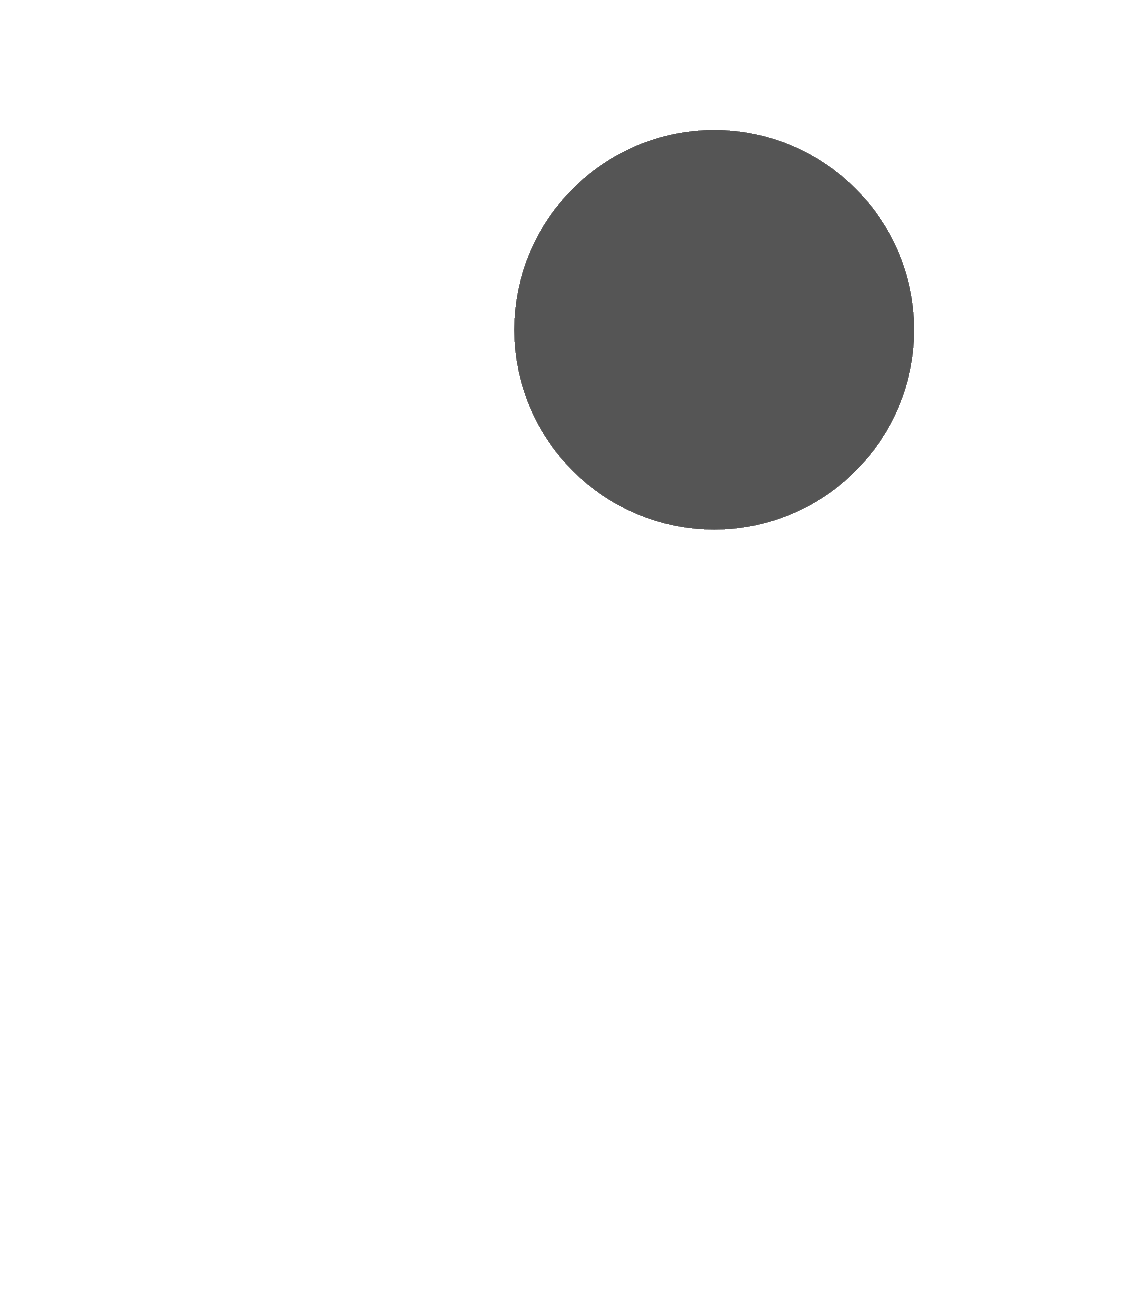


%Convert for calculations
blueCircle = double(blueCircle());

%Grayscale for edge detection
gLayer = uint8( (blueCircle(:,:,1)+blueCircle(:,:,2)+blueCircle(:,:,3))/3 );
g(:,:,1) = gLayer;
g(:,:,2) = gLayer;
g(:,:,3) = gLayer;

%Show image
imshow(g)


%Convert to gray scale to simplify calculations
[rows, cols] = size(gLayer);
sum(gLayer);
blueCols = find(sum(gLayer)<255*rows);
blueWidth = blueCols(end) - blueCols(1) + 1;

%Find Center
[~, blueCx] = min(sum(gLayer))

blueCx = 564

[~, blueCy] = min(sum(gLayer'))

blueCy = 285


%Report
blueCircleArea = round(pi*(blueWidth/2)^2);
fprintf('The Blue Circle is located at (%d,%d) with a diameter of %d pixles and an area of %d pixels^2 and it takes up %%%5.1f of the image.\n,' ...
    ,blueCx, blueCy, blueWidth, blueCircleArea, 100*(blueCircleArea/(rows*cols)) );

The Blue Circle is located at (564,285) with a diameter of 400 pixles and an area of 125664 pixels^2 and it takes up % 13.4 of the image.
,